# Analyze Data from Follow-Up Experiments

% Standard MATLAB initialization - ensure reproducibility
clear; clc; clf;
rng default;
ver % display version information

-----------------------------------------------------------------------------------------
MATLAB Version: 24.2.0.2806996 (R2024b) Update 3
MATLAB License Number: 41249549
Operating System: macOS  Version: 15.5 Build: 24F74 
Java Version: Java 11.0.25+9-LTS with Amazon.com Inc. OpenJDK 64-Bit Server VM mixed mode
-----------------------------------------------------------------------------------------
MATLAB                                                Version 24.2        (R2024b)
Statistics and Machine Learning Toolbox               Version 24.2        (R2024b)
Symbolic Math Toolbox                                 Version 24.2        (R2024b)


## Read Raw Data

### Initial Experiments

filePath = "../Raw Data/Initial Experiments/";
lasITable = readData(FileName=filePath+"lasi all data.xlsx");

### Follow-Up Experiments

filePath = "../Raw Data/Followup Experiments/";
lasITable2 = addConcentrations(Table=sortColumns(Table=[
    readData2(FileName=filePath+"QS E2T5 lasI Plate 1 5.20.xlsx", plateNumber="1") ;
    readData2(FileName=filePath+"QS E2T5 lasI Plate 2 5.20.xlsx", plateNumber="2") ;
    readData2(FileName=filePath+"QS E2T5 lasI Plate 3 5.20.xlsx", plateNumber="3")
    ]));

### Consolidate Data

allLasITable = combineTables(table1=lasITable, table2=lasITable2);

### Save Copy

writetable(allLasITable, "../Data/Combined lasI.csv");

## Check Data

Visualizations of the data to help check for errors.

### Follow-Up Data Time Course

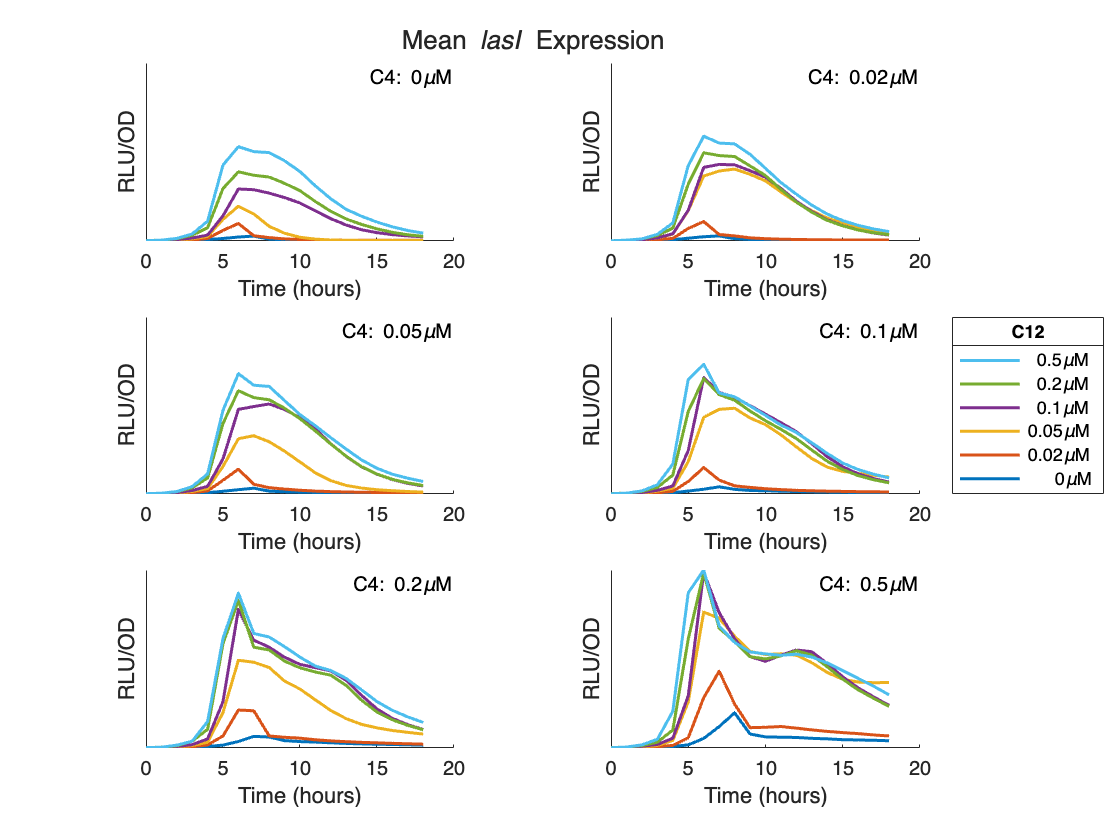

meanLasIData = calculateMeanValues(Table=lasITable2);

figure;
PlotTimeCourse(MeanData=meanLasIData, Gene="lasI", TileParam="C4")

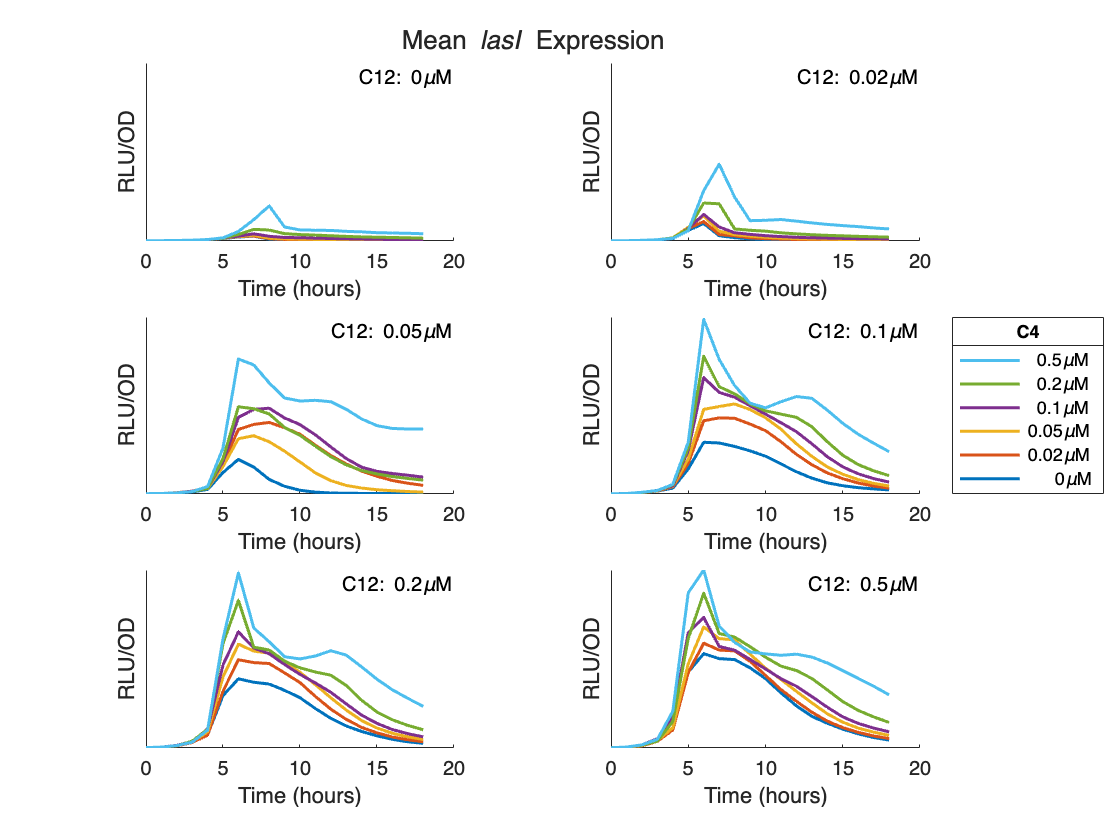

figure
PlotTimeCourse(MeanData=meanLasIData, Gene="lasI", TileParam="C12")

### Combined Single Signal Response

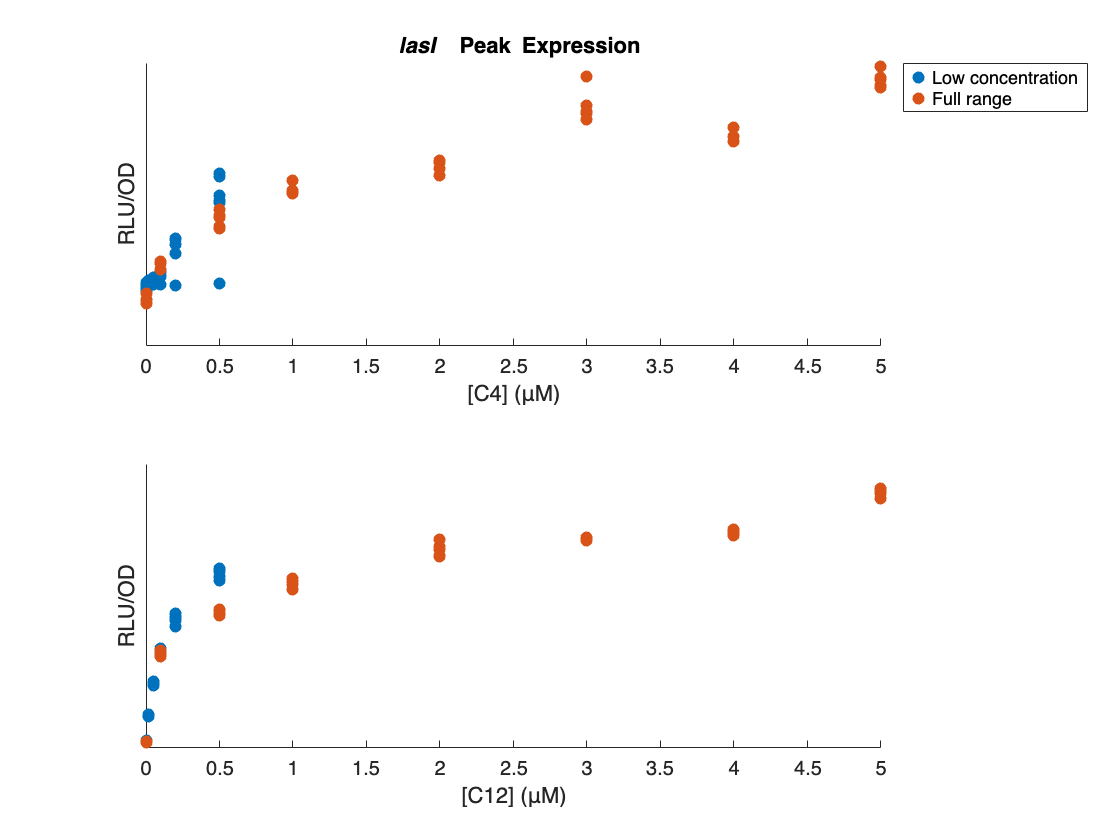

peakLasI = allLasITable( ...
    (allLasITable.Time == 9 & allLasITable.Phase == 'initial') | ...
    (allLasITable.Time == 6 & allLasITable.Phase == 'followup'), ...
    :);

figure
tiledlayout(2, 1);
nexttile
PlotSingleSignal(Gene="lasI", Signal="C4", Data=peakLasI, Legend=true)
nexttile
PlotSingleSignal(Gene="lasI", Signal="C12", Data=peakLasI, Title=false)

### Comparing Expression Level Values

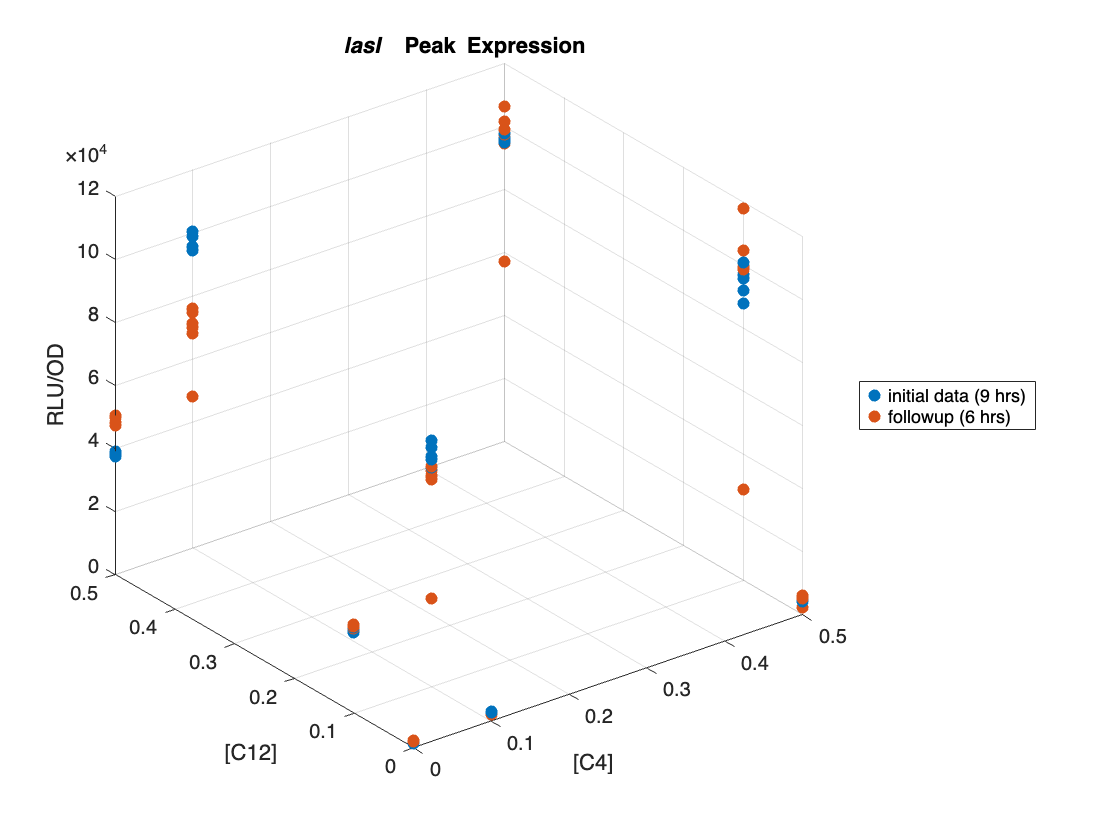

figure
PlotCommonPoints(PeakData=peakLasI, Gene="lasI");

## Local Functions

### Functions to Parse and Format Data from Initial Experiments

function table = readData(args)
    arguments
        args.FileName string
    end

    fileOptions = detectImportOptions(args.FileName, VariableNamingRule="preserve");
    table = readtable(args.FileName, fileOptions);
    table.Var1 = [];
    table.("RU/OD") = [];
    table.RLU_OD = table.RLU ./ table.OD;

end

### Functions to Parse and Format Data from Follow-Up Experiments

The second round of experiments provides luminescence and optical density data for *lasI* and *rhlI* for various combinations of signal concentrations at multiple timepoints. The plate maps for all genes have the same layout:

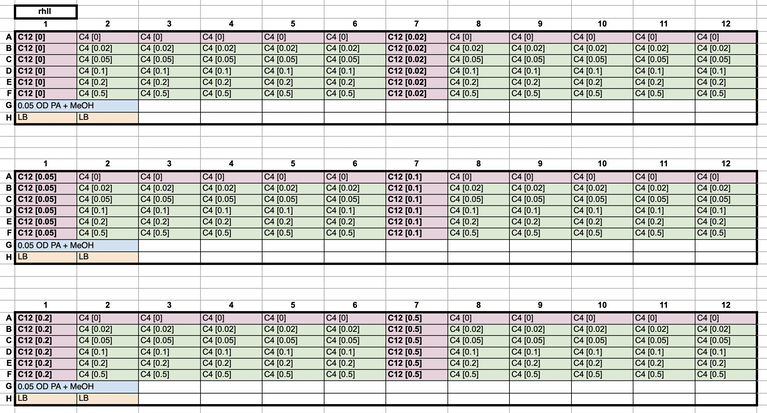

% Function that unpacks tables so that each row contains a single measure
function unpackedTable = unpackTable(args)
    arguments
        args.Table table
        args.Measure string
    end
    
    packedTable = args.Table;
    measure = args.Measure;
    
    % Each row in the table has a measurement for every plate well at a given
    % timepoint. Restructure the table to place a single measurement in each
    % row, creating a separate row for each plate well.
    unpackedTable = stack(packedTable, 3:width(packedTable), ...
        IndexVariableName="PlateWell", ...
        NewDataVariableName=measure);
    
    % Create separate columns for plate row and cell from the plate well
    unpackedTable.PlateRow = categorical( ...
        arrayfun(@(c) char(extract(string(c),1)), unpackedTable.PlateWell, UniformOutput=false));
    unpackedTable.PlateColumn = categorical( ...
        arrayfun(@(c) char(extractAfter(string(c),1)), unpackedTable.PlateWell, UniformOutput=false));
    unpackedTable.PlateWell = [];
    
    % Reorder the columns
    unpackedTable = unpackedTable(:, [2, 1, 4, 5, 3]);
    
    % Remove control values and unused rows
    unpackedTable = unpackedTable(unpackedTable.PlateRow ~= 'G', :);
    unpackedTable = unpackedTable(unpackedTable.PlateRow ~= 'H', :);
end

function table = readData2(args)
    arguments
        args.FileName string
        args.PlateNumber string
    end

    fileName = args.FileName;
    plateNumber = args.PlateNumber;
    
    % The data we want from each file is contained in two embedded tables with
    % the first column (which lackes a heading) labeling each. When we import
    % the data, make sure that first column is a string so we can use it. While
    % we're fixing the data types, ensure that column A12 is interpretted as a
    % number rather than text. By default, MATLAB will interpret it as a cell
    % array since there are some rows (unused in our analysis) that have text
    % in that column.
    % 
    % The two embedded tables are indexed by the measurement time relative to the
    % start of the experiment. We want to ensure that the time is interpretted
    % correctly and ignore any rows lacking a time value. That still leaves some
    % extraneous rows without any data; we can remove them by ensuring that A1 is
    % present.
    
    fileOptions = detectImportOptions(fileName, VariableNamingRule="preserve");
    fileOptions = setvartype(fileOptions, 'Var1', 'string');
    fileOptions = setvartype(fileOptions, 'A12', 'double');
    fileOptions = setvartype(fileOptions, 'Time', 'duration');
    table = readtable(fileName, fileOptions);

    table = table(~ismissing(table.Time) & ~ismissing(table.A1), :);
    
    % Convert the Time column (currently formatted as a duration) to an integer
    % number of hours. Also remove columns we don't need.
    table.Time = hours(round(table.Time, "hours"));
    table.("T° Od600:600") = []; % remove Temperature

    % Discard data after 18 hours so that all plates are consistent
    table(table.Time > 18, :) = [];
    
    % Include the plate number by reusing the first column; on import, that
    % column was used to label the embedded tables.
    table = renamevars(table, 'Var1', 'PlateNumber');
    table.PlateNumber(:) = plateNumber;
    table.PlateNumber = categorical(cellstr(table.PlateNumber));
    
    % At this point we have two tables stacked on top of each other. The top
    % table has optical density values and the bottom one has luminescence
    % data. Split them up.
    odTable = table(1:floor(height(table)/2), :);
    rluTable = table(floor(height(table)/2)+1:end, :);
        
    % Unpack each of the RLU and OD tables and then recombine them into a
    % single table where each row has both an RLU and an OD measurement.
    odTable = unpackTable(Table=odTable, Measure="OD");
    rluTable = unpackTable(Table=rluTable, Measure="RLU");
    table = innerjoin(rluTable, odTable);
    
    % Normalize RLU to OD as a new column
    table.RLU_OD = table.RLU ./ table.OD;
end

function sortedTable = sortColumns(args)
    arguments
        args.Table table
    end

    unsortedTable = args.Table;

    % Sort columns as numeric values instead of strings
    unsortedTable.NumericColumn = str2double(string(unsortedTable.PlateColumn));
    sortedTable = sortrows(unsortedTable, {'Time', 'PlateNumber', 'PlateRow', 'NumericColumn'});
    sortedTable.NumericColumn = [];
end

function c4 = getC4(args)
    arguments
        args.PlateRow categorical
    end

    switch args.PlateRow
        case 'A'
            c4 = 0;
        case 'B'
            c4 = 0.02;
        case 'C'
            c4 = 0.05;
        case 'D'
            c4 = 0.1;
        case 'E'
            c4 = 0.2;
        case 'F'
            c4 = 0.5;
        otherwise
            c4 = NaN;
    end
end

function c12 = getC12(args)
    arguments
        args.PlateNumber categorical
        args.PlateColumn categorical
    end

    c12PlateValues = @(plate1Value, plate2Value, plate3Value) ...
        (args.PlateNumber == '1') .* plate1Value + ...
        (args.PlateNumber == '2') .* plate2Value + ...
        (args.PlateNumber == '3') .* plate3Value;

    switch args.PlateColumn
        case {'1','2','3','4','5','6'}
            c12 = c12PlateValues(0.00, 0.05, 0.2);
        case {'7', '8', '9','10','11', '12'}
            c12 = c12PlateValues(0.02, 0.1, 0.5);
        otherwise
            c12 = NaN;
    end
end

function fullTable = addConcentrations(args)
    arguments
        args.Table table
    end

    fullTable = args.Table;
    fullTable.C4 = arrayfun( ...
        @(plateRow) getC4(plateRow=plateRow), ...
        fullTable.PlateRow ...
        );

    fullTable.C12 = arrayfun( ...
        @(plateNumber, plateColumn) getC12(PlateNumber=plateNumber, PlateColumn=plateColumn), ...
        fullTable.PlateNumber, fullTable.PlateColumn ...
        );
end

function meanData = calculateMeanValues(args)
    arguments
        args.Table table
    end

    meanData = groupsummary(args.Table, ["Time","C12","C4"], "mean", "RLU_OD");
    meanData = renamevars(meanData, "mean_RLU_OD", "RLU_OD");
    meanData.GroupCount = [];
end

### Functions to Consolidate Data

function combinedTable = combineTables(args)
    arguments
        args.table1 table
        args.table2 table
    end

    combinedTable = args.table1;
    combinedTable.Phase = repmat(categorical("initial"), height(combinedTable), 1);
    combinedTable = combinedTable(:, {'Time', 'C4', 'C12', 'RLU', 'OD', 'RLU_OD', 'Phase'});
    tmp = args.table2;
    tmp.Phase = repmat(categorical("followup"), height(tmp), 1);
    combinedTable = [combinedTable; tmp(:, {'Time', 'C4', 'C12', 'RLU', 'OD','RLU_OD', 'Phase'})];
    combinedTable = sortrows(combinedTable, {'Time', 'C4', 'C12'});
end

### Plotting Functions

function PlotTimeCourse(args)
    arguments
        args.MeanData table
        args.Gene string
        args.TileParam string = "C4"
    end

    data = args.MeanData;

    C4Values = unique(data.C4)';
    C12Values = unique(data.C12)';

    if args.TileParam == "C4"
        tileValues = C4Values;
        lineParam = "C12";
        lineValues = C12Values;
    else
        tileValues = C12Values;
        lineParam = "C4";
        lineValues = C4Values;
    end

    timeCourse = tiledlayout(length(tileValues)/2, 2);
    yLimits = [0, max(data.RLU_OD)];
    x = unique(data.Time);

    for tileValue = tileValues
        nexttile;
        hold on
        for lineValue = lineValues
            if args.TileParam == "C4"
                y = data{data.C4 == tileValue & data.C12 == lineValue, "RLU_OD"};
            else
                y = data{data.C4 == lineValue & data.C12 == tileValue, "RLU_OD"};
            end
            
            plot(x, y, LineWidth=1.5);
            yticks({});
            ylabel("RLU/OD");
            xlabel("Time (hours)");
        end
        ylim(yLimits);
        text(1, 0.85, args.TileParam + ": " + num2str(tileValue) + "\muM", ...
            Units="normalized", HorizontalAlignment="right", VerticalAlignment="bottom");
        hold off
    end
    lTimeCourse = legend( ...
        cellfun(@(s) s + "\muM", cellstr(num2str(lineValues'))), ...
        Location="eastoutside", Direction="reverse");
    lTimeCourse.Layout.Tile = 'east';
    lTimeCourse.Title.String = lineParam;
    title(timeCourse, ["Mean{\it " + args.Gene + "} Expression"]);
end

function PlotSingleSignal(args)
    arguments
        args.Signal string
        args.Gene string
        args.Data table
        args.Legend logical = false
        args.Title logical = true
    end

    if (args.Signal == "C4")
        x1 = args.Data(args.Data.C12 == 0 & args.Data.Phase == 'followup', 'C4');
        y1 = args.Data(args.Data.C12 == 0 & args.Data.Phase == 'followup', 'RLU_OD');
        x2 = args.Data(args.Data.C12 == 0 & args.Data.Phase == 'initial', 'C4');
        y2 = args.Data(args.Data.C12 == 0 & args.Data.Phase == 'initial', 'RLU_OD');
    else
        x1 = args.Data(args.Data.C4 == 0 & args.Data.Phase == 'followup', 'C12');
        y1 = args.Data(args.Data.C4 == 0 & args.Data.Phase == 'followup', 'RLU_OD');
        x2 = args.Data(args.Data.C4 == 0 & args.Data.Phase == 'initial', 'C12');
        y2 = args.Data(args.Data.C4 == 0 & args.Data.Phase == 'initial', 'RLU_OD');
    end

    hold on;
    scatter(x1{:, 1}, y1{:, 1}, 'filled');
    scatter(x2{:, 1}, y2{:, 1}, 'filled');
    hold off;
    yticks({});
    ylabel("RLU/OD");
    xlabel("[" + args.Signal + "] (μM)");
    if (args.Title)
        title("{\it " + args.Gene + "}{\rm {\bf Peak Expression}}");
    end
    if args.Legend
        legend({'Low concentration', 'Full range'}, ...
            FontSize=9, ...
            Location="northeastoutside");
    end
end

function PlotCommonPoints(args)
    arguments
        args.PeakData table
        args.Gene string
    end

    peakData = args.PeakData;
    commonData = peakData(peakData.C4 == 0 | peakData.C4 == 0.1 | peakData.C4 == 0.5, :);
    commonData = commonData(commonData.C12 == 0 | commonData.C12 == 0.1 | commonData.C12 == 0.5, :);
    common1 = commonData(commonData.Phase == 'initial', :);
    common2 = commonData(commonData.Phase == 'followup', :);

    scatter3(common1.C4, common1.C12, common1.RLU_OD, "filled");
    hold on;
    scatter3(common2.C4, common2.C12, common2.RLU_OD, "filled");
    hold off;
    xlabel("[C4]");
    ylabel("[C12]");
    zlabel("RLU/OD");
    legend({'initial data (9 hrs)', 'followup (6 hrs)'}, Location='eastoutside');
    title("{\it " + args.Gene + "}{\rm {\bf Peak Expression}}");
end